clear;close all;clc

Head Plant

% wn = 50; % head natural frequency [rad/s]
% z = 1.2; % head damping ratio []
% I = 0.0895*(10^(-3))^(3); % head inertia about rotation point [kg*m^2]
% k = wn^(2)*I; % head stiffness [N*m/rad]
% cc = 2*sqrt(k*I); % head critical damping [N*m*s/rad]
% c = z*cc; % head damping [N*m*s/rad]

I = 1;
k = 1;
cc = 2*sqrt(k*I)

cc = 2

c = 1;

P = tf(1,[c k])


P =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



Visual System

wc = 2*pi*0.1;
V = tf(wc,[1 wc])


V =
 
    0.6283
  ----------
  s + 0.6283
 
Continuous-time transfer function.



V = 1;

Head Controller

C1 = tf(1);

Wing Controller

C2 = tf(1);

Controller Matrix

C = [C1 C2]


C =
 
  From input 1 to output:
  1
 
  From input 2 to output:
  1
 
Static gain.



Open-Loop TF

OL = V*C*P


OL =
 
  From input 1 to output:
    1
  -----
  s + 1
 
  From input 2 to output:
    1
  -----
  s + 1
 
Continuous-time transfer function.



Head Closed-Loop TF

CL_1 = V*C(1)*P/(1+V*C(1)*P)


CL_1 =
 
      s + 1
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.



Wing Closed-Loop TF

CL_2 = V*C(2)/(1+V*C(1)*P)


CL_2 =
 
  s + 1
  -----
  s + 2
 
Continuous-time transfer function.




figure (2) ; clf ; hold on
data = [CL_1 CL_2 OL(1)]


data =
 
  From input 1 to output:
      s + 1
  -------------
  s^2 + 3 s + 2
 
  From input 2 to output:
  s + 1
  -----
  s + 2
 
  From input 3 to output:
    1
  -----
  s + 1
 
Continuous-time transfer function.



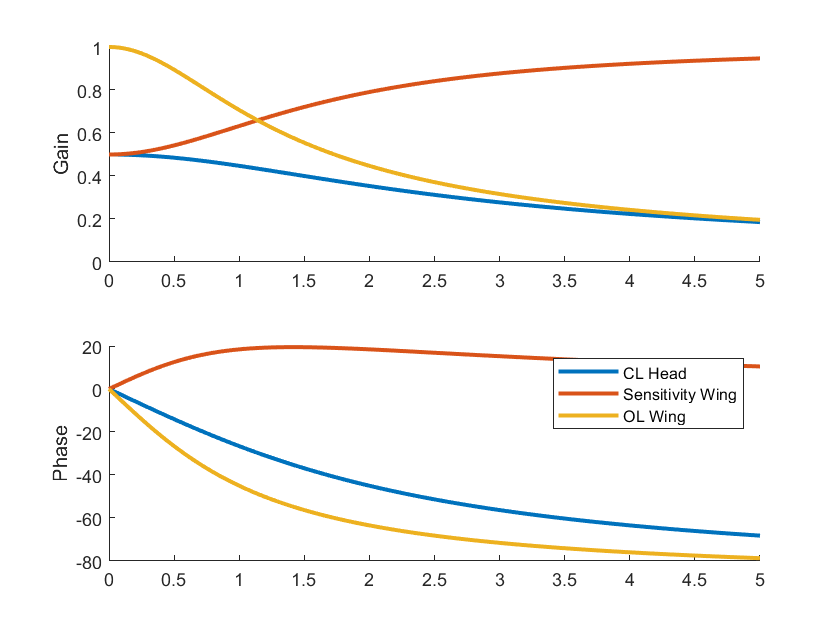

for kk = 1:length(data)   
    w = 0:0.01:5;
    [mag,phase,wout] = bode(data(kk),w);
    subplot(2,1,1) ; hold on
    ylabel('Gain')
    plot(wout,mag(:),'LineWidth',2)
    subplot(2,1,2) ; hold on
    ylabel('Phase')
    plot(wout,phase(:),'LineWidth',2)
end
legend('CL Head','Sensitivity Wing','OL Wing')